[I,x] = intadapt(@sqrt,0,1,1e-10);
err = I - 2/3

err =     -1.907372815246333e-09


number_of_nodes = length(x)

number_of_nodes =    221


The adaptive integrator was reasonably successful. But if we integrate $1/\sqrt{x}$, which in unbounded at the origin, the number of nodes goes up dramatically. 

[I,x] = intadapt(@(x) 1./sqrt(x),eps,1,1e-10);
err = I - 2

err =     -2.428207457327858e-08


number_of_nodes = length(x)

number_of_nodes =    973


The nodes are packed in very closely at the origin; in fact they are placed with exponential spacing.

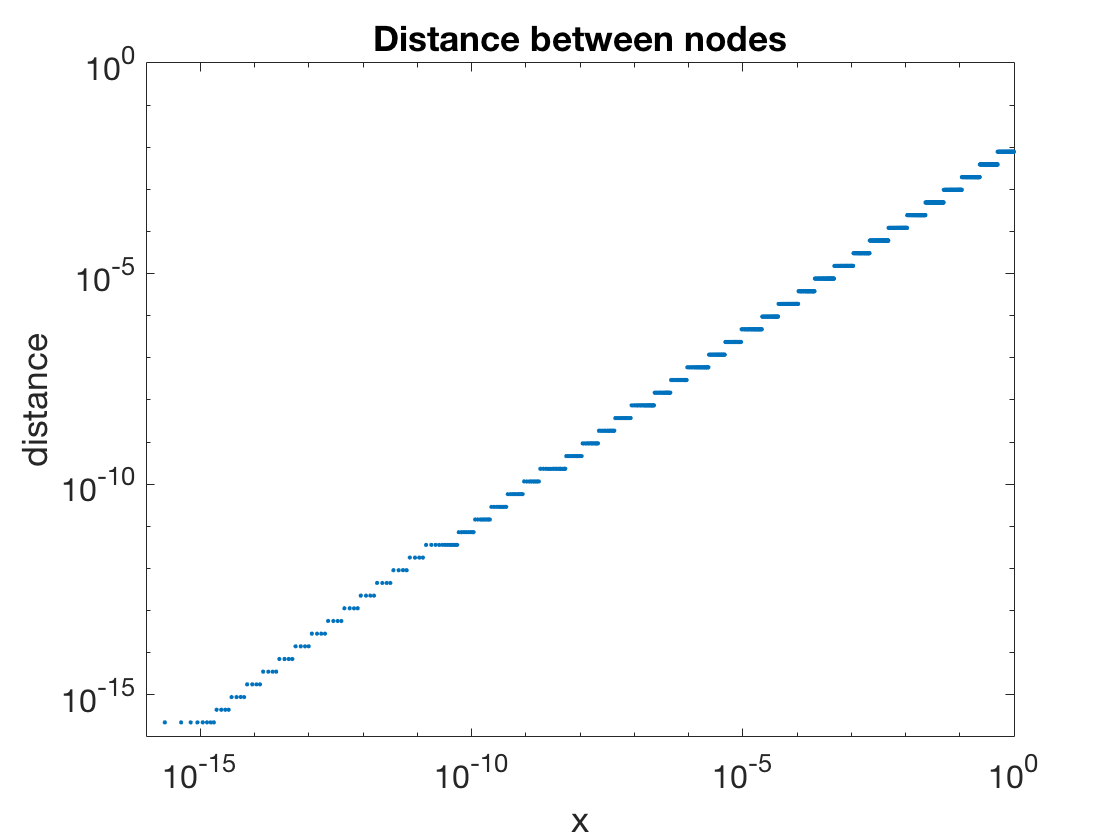

loglog(x(1:end-1),diff(x),'.')
xlabel('x'), ylabel('distance')  % ignore this line
title('Distance between nodes')  % ignore this line
xlim([1e-16 1]), ylim([1e-16 1])